%% ============================================================
%  LANDSLIDE SLOPE STABILITY DIGITAL TWIN
%  MATLAB + Dashboard
% =============================================================

clear;
clc;
close all;

%% ============================================================
% 1. GEOGRAPHICAL GRID
% =============================================================

gridSize = 100;

[x,y] = meshgrid(1:gridSize,1:gridSize);


%% ============================================================
% 2. TERRAIN / ELEVATION
% ============================================================

terrain = 150 - 0.8*x ...
    + 10*exp(-((x-70).^2 + (y-50).^2)/500);


%% ============================================================
% 3. TERRAIN GRADIENT
% ============================================================

[dzdx,dzdy] = gradient(terrain);


%% ============================================================
% 4. SLOPE CALCULATION
% ============================================================

slope = atan(sqrt(dzdx.^2 + dzdy.^2));

slopeDegrees = rad2deg(slope);


%% ============================================================
% 5. TERRAIN INFORMATION
% ============================================================

fprintf("\n");
fprintf("============================================\n");

fprintf("        TERRAIN INFORMATION\n");

        TERRAIN INFORMATION


fprintf("============================================\n");


fprintf("Grid size: %d x %d\n",gridSize,gridSize);

Grid size: 100 x 100



fprintf("Minimum elevation: %.2f m\n", ...
    min(terrain(:)));

Minimum elevation: 70.01 m



fprintf("Maximum elevation: %.2f m\n", ...
    max(terrain(:)));

Maximum elevation: 149.20 m



fprintf("Average elevation: %.2f m\n", ...
    mean(terrain(:)));

Average elevation: 111.13 m



fprintf("\n");

fprintf("        SLOPE INFORMATION\n");

        SLOPE INFORMATION



fprintf("Minimum slope: %.2f degrees\n", ...
    min(slopeDegrees(:)));

Minimum slope: 22.63 degrees



fprintf("Maximum slope: %.2f degrees\n", ...
    max(slopeDegrees(:)));

Maximum slope: 49.79 degrees



fprintf("Average slope: %.2f degrees\n", ...
    mean(slopeDegrees(:)));

Average slope: 38.54 degrees


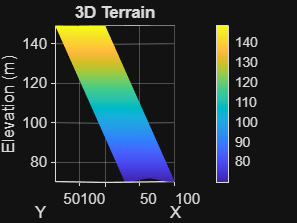



%% ============================================================
% 6. 3D TERRAIN
% ============================================================

figure( ...
    'Name','3D Terrain', ...
    'NumberTitle','off');

surf(x,y,terrain);

xlabel("X");
ylabel("Y");
zlabel("Elevation (m)");

title("3D Terrain");

colorbar;

shading interp;

axis tight;

view(35.9,-0.2);

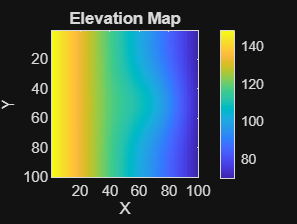


drawnow;


%% ============================================================
% 7. ELEVATION MAP
% ============================================================

figure( ...
    'Name','Elevation Map', ...
    'NumberTitle','off');

imagesc(x(1,:),y(:,1),terrain);

xlabel("X");
ylabel("Y");

title("Elevation Map");

colorbar;

axis equal;
axis tight;

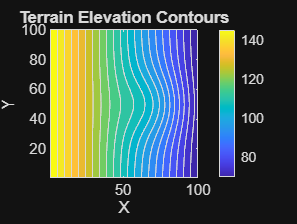


drawnow;


%% ============================================================
% 8. TERRAIN CONTOUR
% ============================================================

figure( ...
    'Name','Terrain Contour', ...
    'NumberTitle','off');

contourf(x,y,terrain,20);

xlabel("X");
ylabel("Y");

title("Terrain Elevation Contours");

colorbar;

axis equal;
axis tight;

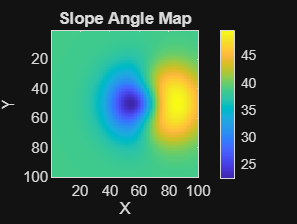


drawnow;


%% ============================================================
% 9. SLOPE MAP
% ============================================================

figure( ...
    'Name','Slope Angle Map', ...
    'NumberTitle','off');

imagesc( ...
    x(1,:), ...
    y(:,1), ...
    slopeDegrees);

xlabel("X");
ylabel("Y");

title("Slope Angle Map");

colorbar;

axis equal;
axis tight;


drawnow;


%% ============================================================
% 10. SOIL PROPERTIES
% ============================================================

% Uniform soil properties

cohesion = 15;          % kPa

frictionAngle = 30;     % degrees

soilDensity = 1800;     % kg/m^3

soilDepth = 5;          % meters


%% ============================================================
% 11. SOIL UNIT WEIGHT
% ============================================================

gamma = soilDensity * 9.81 / 1000;

% gamma is in kN/m^3


%% ============================================================
% 12. CONVERT ANGLES TO RADIANS
% ============================================================

slopeRadians = deg2rad(slopeDegrees);

frictionRadians = deg2rad(frictionAngle);


%% ============================================================
% 13. DRY FACTOR OF SAFETY
% ============================================================

FoS = ...
    (cohesion + ...
    gamma*soilDepth.* ...
    (cos(slopeRadians).^2).* ...
    tan(frictionRadians)) ...
    ./ ...
    (gamma*soilDepth.* ...
    sin(slopeRadians).* ...
    cos(slopeRadians));


%% ============================================================
% 14. DRY FACTOR OF SAFETY INFORMATION
% ============================================================

fprintf("\n");
fprintf("============================================\n");

fprintf("        DRY FACTOR OF SAFETY\n");

        DRY FACTOR OF SAFETY


fprintf("============================================\n");


fprintf("Minimum FoS: %.2f\n", ...
    min(FoS(:)));

Minimum FoS: 0.83



fprintf("Maximum FoS: %.2f\n", ...
    max(FoS(:)));

Maximum FoS: 1.86



fprintf("Average FoS: %.2f\n", ...
    mean(FoS(:)));

Average FoS: 1.09


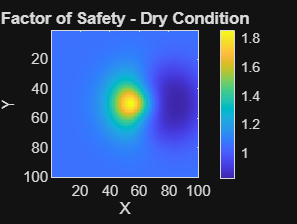



%% ============================================================
% 15. DRY FACTOR OF SAFETY MAP
% ============================================================

figure( ...
    'Name','Dry Factor of Safety Map', ...
    'NumberTitle','off');

imagesc( ...
    x(1,:), ...
    y(:,1), ...
    FoS);

xlabel("X");
ylabel("Y");

title("Factor of Safety - Dry Condition");

colorbar;

axis equal;
axis tight;

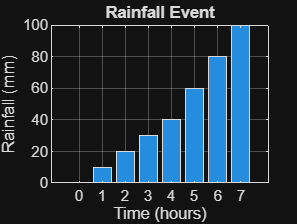


drawnow;


%% ============================================================
% 16. RAINFALL DATA
% ============================================================

% Rainfall added during each hour

rainfall = [0 10 20 30 40 60 80 100];

% Time

time = 0:7;


%% ============================================================
% 17. RAINFALL EVENT
% ============================================================

figure( ...
    'Name','Rainfall Event', ...
    'NumberTitle','off');

bar(time,rainfall);

xlabel("Time (hours)");

ylabel("Rainfall (mm)");

title("Rainfall Event");

grid on;

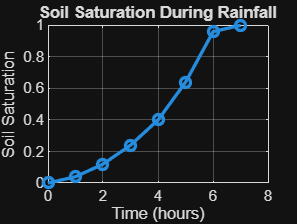


drawnow;


%% ============================================================
% 18. INFILTRATION
% ============================================================

% Fraction of rainfall entering the soil

infiltrationFraction = 0.60;


% Calculate infiltrated rainfall

infiltratedRain = ...
    rainfall * infiltrationFraction;


%% ============================================================
% 19. SOIL WATER CAPACITY
% ============================================================

soilWaterCapacity = 150;     % mm


% Storage at every time step

soilWater = ...
    zeros(size(rainfall));


%% ============================================================
% 20. SOIL WATER CALCULATION
% ============================================================

for t = 1:length(rainfall)

    if t == 1

        soilWater(t) = ...
            min( ...
            infiltratedRain(t), ...
            soilWaterCapacity);

    else

        soilWater(t) = ...
            min( ...
            soilWater(t-1) + ...
            infiltratedRain(t), ...
            soilWaterCapacity);

    end

end


%% ============================================================
% 21. SOIL SATURATION
% ============================================================

soilSaturation = ...
    soilWater / soilWaterCapacity;

soilSaturation = ...
    min(soilSaturation,1);


%% ============================================================
% 22. SOIL SATURATION GRAPH
% ============================================================

figure( ...
    'Name','Soil Saturation', ...
    'NumberTitle','off');

plot( ...
    time, ...
    soilSaturation, ...
    "-o", ...
    "LineWidth",2);

xlabel("Time (hours)");

ylabel("Soil Saturation");

title("Soil Saturation During Rainfall");

ylim([0 1]);

grid on;

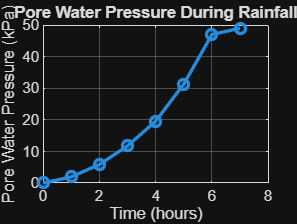


drawnow;


%% ============================================================
% 23. PORE WATER PRESSURE
% ============================================================

gammaWater = 9.81;     % kN/m^3


porePressure = ...
    zeros(size(rainfall));


for t = 1:length(rainfall)

    porePressure(t) = ...
        soilSaturation(t) * ...
        gammaWater * ...
        soilDepth;

end


%% ============================================================
% 24. PORE PRESSURE GRAPH
% ============================================================

figure( ...
    'Name','Pore Water Pressure', ...
    'NumberTitle','off');

plot( ...
    time, ...
    porePressure, ...
    "-o", ...
    "LineWidth",2);

xlabel("Time (hours)");

ylabel("Pore Water Pressure (kPa)");

title("Pore Water Pressure During Rainfall");

grid on;


drawnow;


%% ============================================================
% 25. FACTOR OF SAFETY DURING RAINFALL
% ============================================================

FoS_time = ...
    zeros( ...
    gridSize, ...
    gridSize, ...
    length(rainfall));


% Prevent division by zero on very flat terrain

slopeRadiansSafe = ...
    max( ...
    slopeRadians, ...
    deg2rad(0.5));


%% ============================================================
% 26. WET FACTOR OF SAFETY CALCULATION
% ============================================================

for t = 1:length(rainfall)

    % Pore water pressure effect

    u = ...
        soilSaturation(t) * ...
        gammaWater * ...
        soilDepth .* ...
        cos(slopeRadiansSafe).^2;


    % Effective normal stress

    effectiveNormalStress = ...
        gamma * soilDepth .* ...
        cos(slopeRadiansSafe).^2 ...
        - u;


    % Factor of Safety

    FoS_time(:,:,t) = ...
        ( ...
        cohesion + ...
        effectiveNormalStress .* ...
        tan(frictionRadians) ...
        ) ...
        ./ ...
        ( ...
        gamma * soilDepth .* ...
        sin(slopeRadiansSafe) .* ...
        cos(slopeRadiansSafe) ...
        );

end


%% ============================================================
% 27. WET CONDITION INFORMATION
% ============================================================

finalFoS = ...
    FoS_time(:,:,end);


fprintf("\n");
fprintf("============================================\n");

fprintf("        FINAL WET CONDITION\n");

        FINAL WET CONDITION


fprintf("============================================\n");


fprintf("Minimum FoS: %.2f\n", ...
    min(finalFoS(:)));

Minimum FoS: 0.56



fprintf("Maximum FoS: %.2f\n", ...
    max(finalFoS(:)));

Maximum FoS: 1.09



fprintf("Average FoS: %.2f\n", ...
    mean(finalFoS(:)));

Average FoS: 0.68


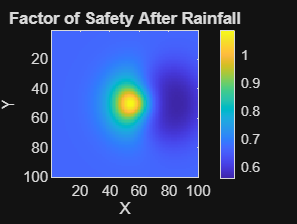



%% ============================================================
% 28. FINAL WET FACTOR OF SAFETY MAP
% ============================================================

figure( ...
    'Name','Wet Factor of Safety', ...
    'NumberTitle','off');

imagesc( ...
    x(1,:), ...
    y(:,1), ...
    finalFoS);

xlabel("X");
ylabel("Y");

title("Factor of Safety After Rainfall");

colorbar;

axis equal;
axis tight;

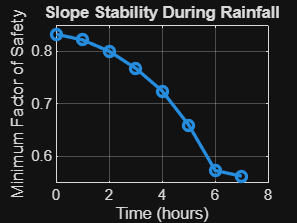


drawnow;


%% ============================================================
% 29. MINIMUM AND AVERAGE FoS OVER TIME
% ============================================================

minimumFoS = ...
    zeros(size(rainfall));

averageFoS = ...
    zeros(size(rainfall));


for t = 1:length(rainfall)

    minimumFoS(t) = ...
        min(FoS_time(:,:,t),[],"all");

    averageFoS(t) = ...
        mean(FoS_time(:,:,t),"all");

end


%% ============================================================
% 30. FoS TREND GRAPH
% ============================================================

figure( ...
    'Name','Slope Stability Over Time', ...
    'NumberTitle','off');

plot( ...
    time, ...
    minimumFoS, ...
    "-o", ...
    "LineWidth",2);

xlabel("Time (hours)");

ylabel("Minimum Factor of Safety");

title("Slope Stability During Rainfall");

grid on;

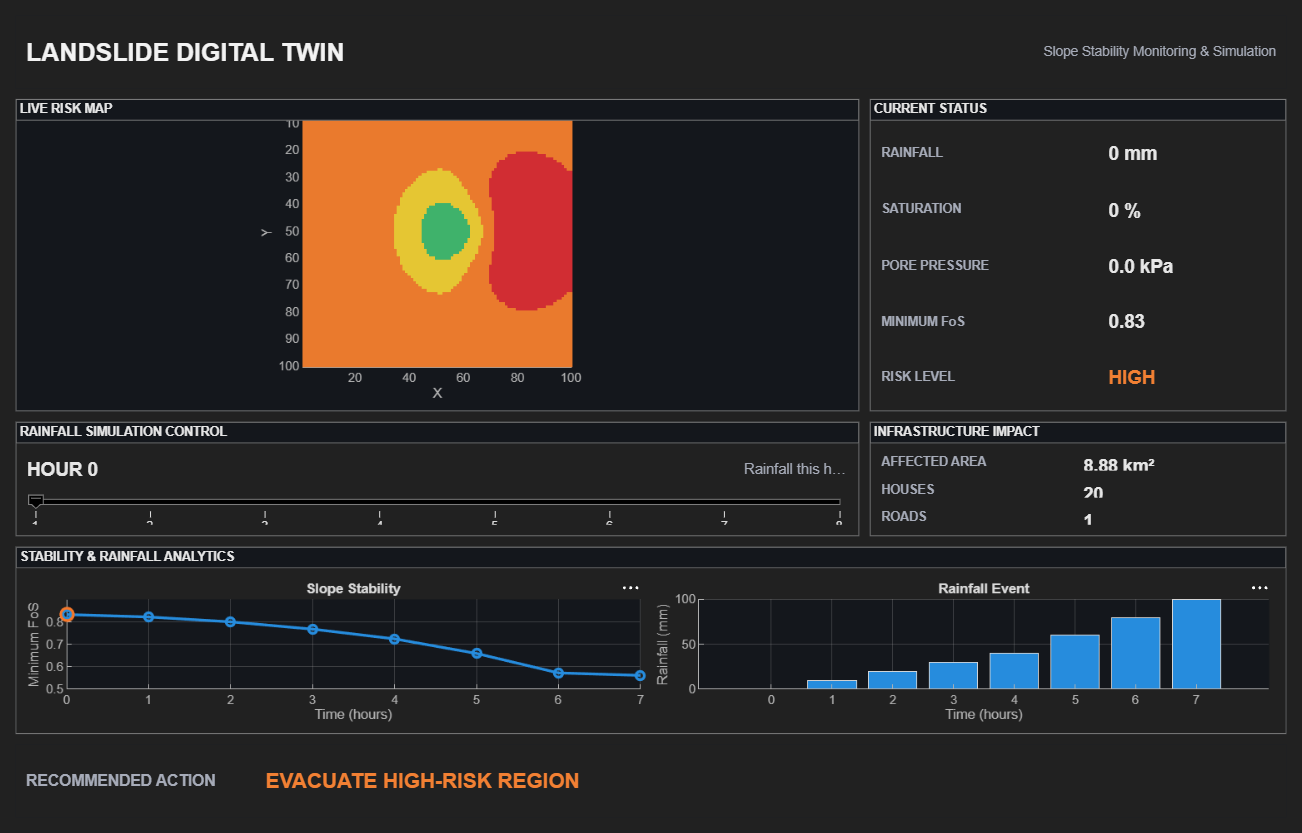


drawnow;


%% ============================================================
% 31. SIMULATED INFRASTRUCTURE
% ============================================================
%
% These are prototype locations for the digital twin.
% They are NOT real geographical infrastructure data.
%

rng(1);


% 24 simulated houses

houses = ...
    [ ...
    randi([10 90],24,1), ...
    randi([10 90],24,1) ...
    ];


% Simulated road

roadX = ...
    linspace(5,95,150)';

roadY = ...
    20 + ...
    0.35*roadX + ...
    8*sin(roadX/12);

roads = ...
    [roadX roadY];


%% ============================================================
% 32. DASHBOARD
% ============================================================

% Create dashboard window

dashboard = uifigure( ...
    'Name','Landslide Digital Twin Dashboard', ...
    'Position',[100 50 1250 800], ...
    'Color',[0.06 0.07 0.09]);


%% ============================================================
% MAIN GRID
% ============================================================

mainGrid = uigridlayout( ...
    dashboard,[5 3]);

mainGrid.RowHeight = ...
    {70,'1x',110,180,70};

mainGrid.ColumnWidth = ...
    {'1x','1x','1x'};

mainGrid.Padding = [15 15 15 15];

mainGrid.RowSpacing = 10;

mainGrid.ColumnSpacing = 10;


%% ============================================================
% HEADER
% ============================================================

headerPanel = uipanel(mainGrid);

headerPanel.Layout.Row = 1;

headerPanel.Layout.Column = [1 3];

headerPanel.BackgroundColor = ...
    [0.10 0.11 0.14];

headerPanel.BorderType = "none";


headerGrid = uigridlayout( ...
    headerPanel,[1 2]);

headerGrid.ColumnWidth = ...
    {'1x','1x'};


titleLabel = uilabel(headerGrid);

titleLabel.Text = ...
    "LANDSLIDE DIGITAL TWIN";

titleLabel.FontSize = 24;

titleLabel.FontWeight = "bold";

titleLabel.FontColor = ...
    [0.95 0.95 0.95];

titleLabel.VerticalAlignment = ...
    "center";


subtitleLabel = uilabel(headerGrid);

subtitleLabel.Text = ...
    "Slope Stability Monitoring & Simulation";

subtitleLabel.HorizontalAlignment = ...
    "right";

subtitleLabel.VerticalAlignment = ...
    "center";

subtitleLabel.FontSize = 13;

subtitleLabel.FontColor = ...
    [0.65 0.67 0.72];


%% ============================================================
% RISK MAP PANEL
% ============================================================

mapPanel = uipanel(mainGrid);

mapPanel.Layout.Row = 2;

mapPanel.Layout.Column = [1 2];

mapPanel.Title = "LIVE RISK MAP";

mapPanel.FontWeight = "bold";

mapPanel.BackgroundColor = ...
    [0.08 0.09 0.11];

mapPanel.ForegroundColor = ...
    [0.9 0.9 0.9];


dashboardAxes = uiaxes(mapPanel);

dashboardAxes.Position = ...
    [10 10 790 310];

dashboardAxes.XColor = ...
    [0.7 0.7 0.7];

dashboardAxes.YColor = ...
    [0.7 0.7 0.7];

dashboardAxes.Color = ...
    [0.08 0.09 0.11];

xlabel(dashboardAxes,"X");

ylabel(dashboardAxes,"Y");

title(dashboardAxes,"Current Landslide Risk");


%% ============================================================
% STATUS PANEL
% ============================================================

statusPanel = uipanel(mainGrid);

statusPanel.Layout.Row = 2;

statusPanel.Layout.Column = 3;

statusPanel.Title = "CURRENT STATUS";

statusPanel.FontWeight = "bold";

statusPanel.BackgroundColor = ...
    [0.08 0.09 0.11];

statusPanel.ForegroundColor = ...
    [0.9 0.9 0.9];


statusGrid = uigridlayout( ...
    statusPanel,[5 2]);

statusGrid.RowHeight = ...
    {'1x','1x','1x','1x','1x'};

statusGrid.ColumnWidth = ...
    {'1.3x','1x'};


%% ============================================================
% STATUS LABELS
% ============================================================

uilabel(statusGrid, ...
    'Text',"RAINFALL", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

rainfallLabel = uilabel(statusGrid);

rainfallLabel.Text = "0 mm";

rainfallLabel.FontSize = 18;

rainfallLabel.FontWeight = "bold";

rainfallLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(statusGrid, ...
    'Text',"SATURATION", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

saturationLabel = uilabel(statusGrid);

saturationLabel.Text = "0 %";

saturationLabel.FontSize = 18;

saturationLabel.FontWeight = "bold";

saturationLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(statusGrid, ...
    'Text',"PORE PRESSURE", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

pressureLabel = uilabel(statusGrid);

pressureLabel.Text = "0 kPa";

pressureLabel.FontSize = 18;

pressureLabel.FontWeight = "bold";

pressureLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(statusGrid, ...
    'Text',"MINIMUM FoS", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

fosLabel = uilabel(statusGrid);

fosLabel.Text = "0";

fosLabel.FontSize = 18;

fosLabel.FontWeight = "bold";

fosLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(statusGrid, ...
    'Text',"RISK LEVEL", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

riskLabel = uilabel(statusGrid);

riskLabel.Text = "LOW";

riskLabel.FontSize = 18;

riskLabel.FontWeight = "bold";

riskLabel.FontColor = ...
    [0.3 0.8 0.45];


%% ============================================================
% INFRASTRUCTURE PANEL
% ============================================================

infrastructurePanel = uipanel(mainGrid);

infrastructurePanel.Layout.Row = 3;

infrastructurePanel.Layout.Column = 3;

infrastructurePanel.Title = ...
    "INFRASTRUCTURE IMPACT";

infrastructurePanel.FontWeight = "bold";

infrastructurePanel.BackgroundColor = ...
    [0.08 0.09 0.11];

infrastructurePanel.ForegroundColor = ...
    [0.9 0.9 0.9];


infraGrid = uigridlayout( ...
    infrastructurePanel,[3 2]);


uilabel(infraGrid, ...
    'Text',"AFFECTED AREA", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

areaLabel = uilabel(infraGrid);

areaLabel.Text = "0 km²";

areaLabel.FontSize = 17;

areaLabel.FontWeight = "bold";

areaLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(infraGrid, ...
    'Text',"HOUSES", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

housesLabel = uilabel(infraGrid);

housesLabel.Text = "0";

housesLabel.FontSize = 17;

housesLabel.FontWeight = "bold";

housesLabel.FontColor = ...
    [0.9 0.9 0.9];


uilabel(infraGrid, ...
    'Text',"ROADS", ...
    'FontWeight',"bold", ...
    'FontColor',[0.65 0.67 0.72]);

roadsLabel = uilabel(infraGrid);

roadsLabel.Text = "0";

roadsLabel.FontSize = 17;

roadsLabel.FontWeight = "bold";

roadsLabel.FontColor = ...
    [0.9 0.9 0.9];


%% ============================================================
% SIMULATION CONTROL PANEL
% ============================================================

controlPanel = uipanel(mainGrid);

controlPanel.Layout.Row = 3;

controlPanel.Layout.Column = [1 2];

controlPanel.Title = ...
    "RAINFALL SIMULATION CONTROL";

controlPanel.FontWeight = "bold";

controlPanel.BackgroundColor = ...
    [0.08 0.09 0.11];

controlPanel.ForegroundColor = ...
    [0.9 0.9 0.9];


controlGrid = uigridlayout( ...
    controlPanel,[2 2]);

controlGrid.RowHeight = ...
    {'1x','1x'};

controlGrid.ColumnWidth = ...
    {'1x',100};


hourLabel = uilabel(controlGrid);

hourLabel.Text = "HOUR 0";

hourLabel.FontSize = 18;

hourLabel.FontWeight = "bold";

hourLabel.FontColor = ...
    [0.9 0.9 0.9];

hourLabel.VerticalAlignment = ...
    "center";


rainValueLabel = uilabel(controlGrid);

rainValueLabel.Text = "Rainfall: 0 mm";

rainValueLabel.FontSize = 14;

rainValueLabel.FontColor = ...
    [0.65 0.67 0.72];

rainValueLabel.HorizontalAlignment = ...
    "right";


timeSlider = uislider(controlGrid);

timeSlider.Limits = ...
    [1 length(rainfall)];

timeSlider.Value = 1;

timeSlider.MajorTicks = ...
    1:length(rainfall);

timeSlider.MinorTicks = [];

timeSlider.Layout.Column = [1 2];


%% ============================================================
% TREND PANEL
% ============================================================

trendPanel = uipanel(mainGrid);

trendPanel.Layout.Row = 4;

trendPanel.Layout.Column = [1 3];

trendPanel.Title = ...
    "STABILITY & RAINFALL ANALYTICS";

trendPanel.FontWeight = "bold";

trendPanel.BackgroundColor = ...
    [0.08 0.09 0.11];

trendPanel.ForegroundColor = ...
    [0.9 0.9 0.9];


trendGrid = uigridlayout( ...
    trendPanel,[1 2]);


%% ============================================================
% FoS TREND AXES
% ============================================================

fosAxes = uiaxes(trendGrid);

fosAxes.XColor = ...
    [0.7 0.7 0.7];

fosAxes.YColor = ...
    [0.7 0.7 0.7];

fosAxes.Color = ...
    [0.08 0.09 0.11];

xlabel(fosAxes,"Time (hours)");

ylabel(fosAxes,"Minimum FoS");

title(fosAxes,"Slope Stability");

grid(fosAxes,"on");


plot( ...
    fosAxes, ...
    time, ...
    minimumFoS, ...
    "-o", ...
    "LineWidth",2);

hold(fosAxes,"on");

currentPoint = plot( ...
    fosAxes, ...
    time(1), ...
    minimumFoS(1), ...
    "o", ...
    "MarkerSize",9, ...
    "LineWidth",2);

hold(fosAxes,"off");


%% ============================================================
% RAINFALL AXES
% ============================================================

rainAxes = uiaxes(trendGrid);

rainAxes.XColor = ...
    [0.7 0.7 0.7];

rainAxes.YColor = ...
    [0.7 0.7 0.7];

rainAxes.Color = ...
    [0.08 0.09 0.11];

xlabel(rainAxes,"Time (hours)");

ylabel(rainAxes,"Rainfall (mm)");

title(rainAxes,"Rainfall Event");

grid(rainAxes,"on");


bar( ...
    rainAxes, ...
    time, ...
    rainfall);


%% ============================================================
% ACTION PANEL
% ============================================================

actionPanel = uipanel(mainGrid);

actionPanel.Layout.Row = 5;

actionPanel.Layout.Column = [1 3];

actionPanel.BackgroundColor = ...
    [0.10 0.11 0.14];

actionPanel.BorderType = "none";


actionGrid = uigridlayout( ...
    actionPanel,[1 2]);

actionGrid.ColumnWidth = ...
    {220,'1x'};


actionTitle = uilabel(actionGrid);

actionTitle.Text = ...
    "RECOMMENDED ACTION";

actionTitle.FontSize = 15;

actionTitle.FontWeight = "bold";

actionTitle.FontColor = ...
    [0.65 0.67 0.72];

actionTitle.VerticalAlignment = ...
    "center";


actionLabel = uilabel(actionGrid);

actionLabel.Text = ...
    "MONITOR REGION";

actionLabel.FontSize = 20;

actionLabel.FontWeight = "bold";

actionLabel.FontColor = ...
    [0.3 0.8 0.45];

actionLabel.VerticalAlignment = ...
    "center";


%% ============================================================
% 33. CONNECT SLIDER TO DASHBOARD
% ============================================================

timeSlider.ValueChangedFcn = ...
    @(src,event) updateDashboard( ...
        src, ...
        dashboardAxes, ...
        fosAxes, ...
        currentPoint, ...
        rainfallLabel, ...
        rainValueLabel, ...
        saturationLabel, ...
        pressureLabel, ...
        fosLabel, ...
        riskLabel, ...
        areaLabel, ...
        housesLabel, ...
        roadsLabel, ...
        hourLabel, ...
        actionLabel, ...
        FoS_time, ...
        rainfall, ...
        soilSaturation, ...
        porePressure, ...
        time, ...
        x, ...
        y, ...
        houses, ...
        roads);


%% ============================================================
% 34. INITIAL DASHBOARD UPDATE
% ============================================================

updateDashboard( ...
    timeSlider, ...
    dashboardAxes, ...
    fosAxes, ...
    currentPoint, ...
    rainfallLabel, ...
    rainValueLabel, ...
    saturationLabel, ...
    pressureLabel, ...
    fosLabel, ...
    riskLabel, ...
    areaLabel, ...
    housesLabel, ...
    roadsLabel, ...
    hourLabel, ...
    actionLabel, ...
    FoS_time, ...
    rainfall, ...
    soilSaturation, ...
    porePressure, ...
    time, ...
    x, ...
    y, ...
    houses, ...
    roads);



%% ============================================================
% END OF MAIN SCRIPT
% ============================================================



%% ============================================================
% DASHBOARD UPDATE FUNCTION
% ============================================================

function updateDashboard( ...
    timeSlider, ...
    dashboardAxes, ...
    fosAxes, ...
    currentPoint, ...
    rainfallLabel, ...
    rainValueLabel, ...
    saturationLabel, ...
    pressureLabel, ...
    fosLabel, ...
    riskLabel, ...
    areaLabel, ...
    housesLabel, ...
    roadsLabel, ...
    hourLabel, ...
    actionLabel, ...
    FoS_time, ...
    rainfall, ...
    soilSaturation, ...
    porePressure, ...
    time, ...
    x, ...
    y, ...
    houses, ...
    roads)

%% ------------------------------------------------------------
% 1. GET CURRENT TIME
% ------------------------------------------------------------

tIndex = round(timeSlider.Value);

% Safety check
tIndex = max(1,min(length(rainfall),tIndex));

currentHour = time(tIndex);


%% ------------------------------------------------------------
% 2. GET CURRENT FoS MAP
% ------------------------------------------------------------

currentFoS = FoS_time(:,:,tIndex);


%% ------------------------------------------------------------
% 3. CREATE RISK MAP
% ------------------------------------------------------------

riskMap = zeros(size(currentFoS));


% LOW RISK
riskMap(currentFoS > 1.5) = 1;


% MODERATE RISK
riskMap(currentFoS >= 1.2 & currentFoS <= 1.5) = 2;


% HIGH RISK
riskMap(currentFoS >= 1.0 & currentFoS < 1.2) = 3;


% EXTREME RISK
riskMap(currentFoS < 1.0) = 4;


%% ------------------------------------------------------------
% 4. CALCULATE RISK PERCENTAGES
% ------------------------------------------------------------

totalCells = numel(currentFoS);

extremePercentage = ...
    sum(currentFoS(:) < 1.0) / totalCells * 100;

highPercentage = ...
    sum(currentFoS(:) >= 1.0 & ...
        currentFoS(:) < 1.2) / totalCells * 100;

moderatePercentage = ...
    sum(currentFoS(:) >= 1.2 & ...
        currentFoS(:) <= 1.5) / totalCells * 100;


%% ------------------------------------------------------------
% 5. DETERMINE OVERALL RISK
% ------------------------------------------------------------

if extremePercentage >= 20

    overallRisk = "EXTREME";
    action = "IMMEDIATE EVACUATION";
    riskColor = [0.90 0.20 0.25];

elseif extremePercentage >= 5 || highPercentage >= 25

    overallRisk = "HIGH";
    action = "EVACUATE HIGH-RISK REGION";
    riskColor = [0.95 0.50 0.20];

elseif highPercentage >= 10 || moderatePercentage >= 25

    overallRisk = "MODERATE";
    action = "ISSUE WARNING";
    riskColor = [0.95 0.78 0.20];

else

    overallRisk = "LOW";
    action = "MONITOR REGION";
    riskColor = [0.30 0.80 0.45];

end


%% ------------------------------------------------------------
% 6. MINIMUM FoS
% ------------------------------------------------------------

currentMinimumFoS = min(currentFoS(:));


%% ------------------------------------------------------------
% 7. UPDATE RISK MAP
% ------------------------------------------------------------

imagesc( ...
    dashboardAxes, ...
    x(1,:), ...
    y(:,1), ...
    riskMap);

axis(dashboardAxes,"equal");
axis(dashboardAxes,"tight");

caxis(dashboardAxes,[1 4]);

colormap(dashboardAxes, ...
    [ ...
    0.25 0.70 0.42
    0.90 0.78 0.20
    0.92 0.48 0.18
    0.82 0.18 0.20
    ]);

title( ...
    dashboardAxes, ...
    sprintf( ...
    "Landslide Risk Map - Hour %.0f", ...
    currentHour));


%% ------------------------------------------------------------
% 8. CALCULATE AFFECTED AREA
% ------------------------------------------------------------

% FoS below 1.2 is considered affected

affectedCells = currentFoS < 1.2;

cellArea = 0.001;     % prototype km² per cell

affectedArea = ...
    sum(affectedCells(:)) * cellArea;


%% ------------------------------------------------------------
% 9. AFFECTED HOUSES
% ------------------------------------------------------------

affectedHouses = 0;


for i = 1:size(houses,1)

    hx = round(houses(i,1));
    hy = round(houses(i,2));

    % Keep coordinates inside grid

    hx = max(1,min(size(currentFoS,2),hx));
    hy = max(1,min(size(currentFoS,1),hy));

    houseFoS = currentFoS(hy,hx);

    if houseFoS < 1.2

        affectedHouses = affectedHouses + 1;

    end

end


%% ------------------------------------------------------------
% 10. AFFECTED ROAD
% ------------------------------------------------------------

affectedRoadPoints = 0;


for i = 1:size(roads,1)

    rx = round(roads(i,1));
    ry = round(roads(i,2));

    % Keep coordinates inside grid

    rx = max(1,min(size(currentFoS,2),rx));
    ry = max(1,min(size(currentFoS,1),ry));

    roadFoS = currentFoS(ry,rx);

    if roadFoS < 1.2

        affectedRoadPoints = affectedRoadPoints + 1;

    end

end


roadPercentage = ...
    affectedRoadPoints / size(roads,1) * 100;


if roadPercentage >= 20

    affectedRoads = 1;

else

    affectedRoads = 0;

end


%% ------------------------------------------------------------
% 11. CURRENT RAINFALL INFORMATION
% ------------------------------------------------------------

cumulativeRainfall = ...
    sum(rainfall(1:tIndex));

currentRainfall = ...
    rainfall(tIndex);

currentSaturation = ...
    soilSaturation(tIndex);

currentPressure = ...
    porePressure(tIndex);


%% ------------------------------------------------------------
% 12. UPDATE DASHBOARD TEXT
% ------------------------------------------------------------

rainfallLabel.Text = ...
    sprintf("%.0f mm",cumulativeRainfall);


rainValueLabel.Text = ...
    sprintf( ...
    "Rainfall this hour: %.0f mm", ...
    currentRainfall);


saturationLabel.Text = ...
    sprintf( ...
    "%.0f %%", ...
    currentSaturation * 100);


pressureLabel.Text = ...
    sprintf( ...
    "%.1f kPa", ...
    currentPressure);


fosLabel.Text = ...
    sprintf( ...
    "%.2f", ...
    currentMinimumFoS);


riskLabel.Text = ...
    overallRisk;


riskLabel.FontColor = ...
    riskColor;


areaLabel.Text = ...
    sprintf( ...
    "%.2f km²", ...
    affectedArea);


housesLabel.Text = ...
    sprintf( ...
    "%d", ...
    affectedHouses);


roadsLabel.Text = ...
    sprintf( ...
    "%d", ...
    affectedRoads);


hourLabel.Text = ...
    sprintf( ...
    "HOUR %.0f", ...
    currentHour);


actionLabel.Text = ...
    action;


actionLabel.FontColor = ...
    riskColor;


%% ------------------------------------------------------------
% 13. UPDATE FoS GRAPH MARKER
% ------------------------------------------------------------

currentPoint.XData = ...
    time(tIndex);

currentPoint.YData = ...
    currentMinimumFoS;


%% ------------------------------------------------------------
% 14. FORCE DASHBOARD REFRESH
% ------------------------------------------------------------

drawnow;

end